## Option pricing study

Shunwen Tan

**1. What dows the volatility curve look like in SP500? Please explain your observation.**

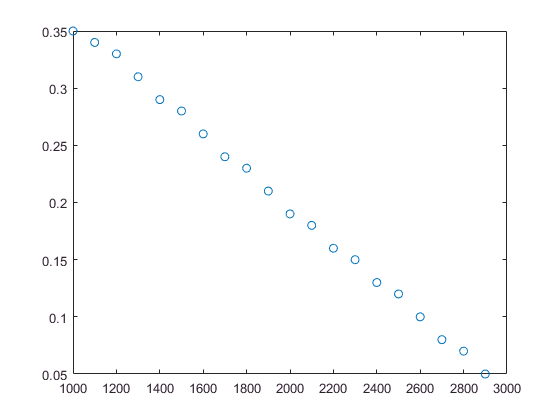

Strike=[2900:-100:1000];Strike=Strike';
ImVol=[0.05;0.07;0.08;0.1;0.12;0.13;0.15;0.16;0.18;0.19;0.21;0.23;0.24;0.26;0.28;0.29;0.31;0.33;0.34;0.35];
plot(Strike,ImVol,'o');

The volatility curve show downward curve shape (reverse skew), which suggests that out-of-the-money puts and in-the-money calls are more expensive. There are some possible explanations:

1) Historically stock markets tend to crash downwards faster than they move upwards, Investors began to worry about market crashes and trade options for protection. There are generally two options trades to hedge the long stock position: purchase downside puts as insurance which increases the demand for downside puts ; Sell calls (covered calls) which decrease demand for upside calls and thus lowers prices (volatility).

2) In-the-money calls have become popular alternatives to outright stock purchases as they offer leverage.

**2. Use the volatility by strike provided above to fit a simple volatility curve. You can assume the curve is linear by strike to start with.**

% fit a simple linear curve to the data
Qfun= @(x,xdata) x(1)+x(2)*xdata;
x0=[0.3,1];
x = lsqcurvefit(Qfun,x0,Strike,ImVol);


Local minimum found.

Optimization completed because the size of the gradient is less than
the default value of the optimality tolerance.

<stopping criteria details>



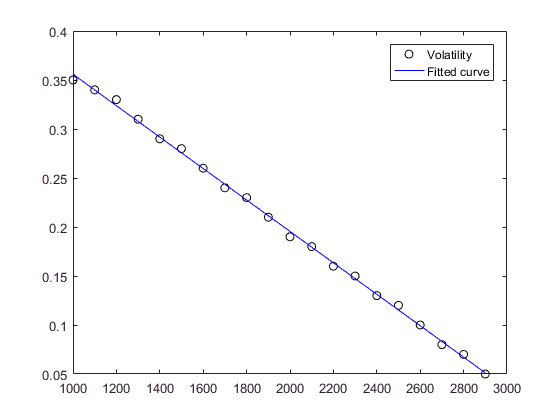

% Visualize the goodness of fit
times = linspace(Strike(1),Strike(end));
plot(Strike,ImVol,'ko',times,Qfun(x,times),'b-')
legend('Volatility','Fitted curve')

**3. Use the fitted volatility curve to calculate the implied probability density function.**

Firstly, construct a butteráy spread  with three call options.  In particular, 

-Long one option at strike $K−\varepsilon$; 

-Short two options at strike K;

 -Long one option at strike $K+\varepsilon$.

Consider a portfolio that contains $\frac{1}{\varepsilon^2 }$ units of a butteráy spread. Its time-t value is therefore


$$V\left(S_t ,K,T,\varepsilon \right)=\frac{C\left(K−\varepsilon \right)−2C\left(K\right)+C\left(K+\varepsilon \right)}{\varepsilon^2 }$$


Then,use the approximation function of Black-Scholes call option, 


$$\frac{\vartheta^2 C\left(K\right)}{\vartheta K^2 }=\frac{\frac{C\left(K+\varepsilon \right)−C\left(K\right)}{\varepsilon }−\frac{C\left(K\right)−C\left(K−\varepsilon \right)}{\varepsilon }}{\varepsilon }=\frac{C\left(K−\varepsilon \right)−2C\left(K\right)+C\left(K+\varepsilon \right)}{\varepsilon^2 }$$


when the limit of $\varepsilon$ converge to 0, the constructed butterfly spread equals $\frac{\vartheta^2 C\left(K\right)}{\vartheta K^2 }$


$$\lim_{\varepsilon \longrightarrow 0} V\left(S_t ,K,T,\varepsilon \right)=\frac{\vartheta^2 C\left(K\right)}{\vartheta K^2 }$$


V can be written as the expected payoff under the risk neutral measure Q, discounted to time t 


$$\begin{array}{l}
\lim_{\varepsilon \longrightarrow 0} V\left(S_t ,K,T,\varepsilon \right)=e^{−r\left(T−t\right)} E_t^Q \left\lbrack \lim_{\varepsilon \longrightarrow 0} V\left(S_T ,K,T,\varepsilon \right)\right\rbrack \\
=e^{−r\left(T−t\right)} \int_K^{\infty } \left(S_T −K\right)p\left(S_T ,T|S_t ,t\right)dS_T \\
=e^{−r\left(T−t\right)} p\left(K,T|S_t ,t\right)
\end{array}$$


where $p\left(K,T|S_t ,t\right)$  denotes the risk neutral density of the terminal stock price $S_T$ . Hence, as $\varepsilon$ converge to 0 , the portfolio approaches the risk neutral density, evaluated at K.

Combining Equations produces 


$$\frac{\vartheta^2 C\left(K\right)}{\vartheta K^2 }=e^{−r\left(T−t\right)} p\left(K,T|S_t ,t\right)$$
 

 We have the discounted risk neutral density is the second derivative of the call price with respect to strike.

With this relationship we can calculate the implied probability density function from fitted volatility: 

1) obtain the fitted market call prices using the Black-Scholes formula and fitted volatility. This produces a set of N strike-price pairs ${\left\lbrace \left(K_i ,C_i \right)\right\rbrace }_{i=1}^N$.

2) Use finite difference approximation to get the risk neutral density at every strike $K_i$ ( $e^{−r\left(T−t\right)}$=1 as assuming interest rate is 0)


$$p\left(K_i ,T|S_t ,t\right)={\frac{\vartheta^2 C\left(K\right)}{\vartheta K^2 }}_{K=K_i } =\frac{C_{i+1} −2C_i +C_{i−1} }{{\left(\text{dK}\right)}^2 }$$


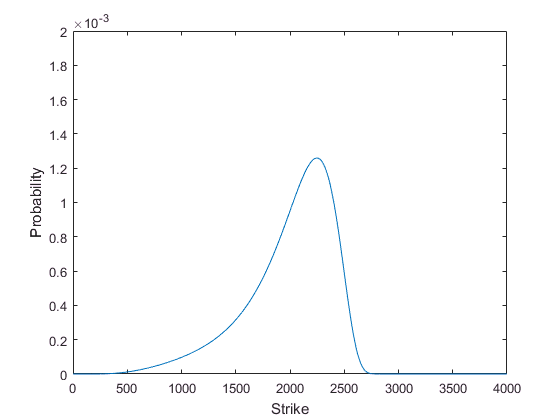

%  spot price
S0=2000;   
% interest rate
r=0;
% time to maturity：1 year
time_maturity=1;
% possible strike price 
  K=0:1:4000;  
% volatility (volatility should be positive)
 sigma=max(Qfun(x,K),0);
% call_price by function blsprice
for k=1:4001
Call(k)=blsprice(S0,  K(k), r,time_maturity, sigma(k), 0);
end

%risk neutral density
for k=2:4000
    p(k)=Call(k+1)-2*Call(k)+Call(k-1);
end

plot(K(2:4000),p(2:4000),'-')
ylim([0 0.002])
xlabel('Strike')
ylabel('Probability')

% area under probability density
sum(p)

ans = 1

**4. Based on Step 3, does the implied distribution have positive or negative skewness? Why？**

Acorrding to the above implied risk neutral density function, the implied distribution have negative skewness. Because the density function is not symmetric and  has longer left tial. 

**5.Can you draw the same conclusion in Step 4 just base on your observation in Step 1?  Why?**

No. Becasue the risk neutral density is sensitive to the fitted implied volitility curve. We only have limited points from step 1 without interplation.

 For example, we don't know the implied volitility when index grow to above 3000, it is possible that there is volatility smile pattern in the real world, but based on existing sample data, we fitted simple straight line to generate more data points. So the conslusion in step 4 is based on the assumption that the volatility curve is linear by strike. And if we fit different curve shape to the data, we may have quite different conclusion.

**6. Please evaluate the implied PDF curve you derived in Step 3. Please list the improvements you would like to add to the study.**

1) **Evaluation: **

In step 3, we derived simple and easy to implement procedures to extract RND. The results presented that the risk neutral density for the S&P 500 index is far from the lognormal density assumed by the Black-Scholes model. It can reflect the negatively skewed and fat-tailed relative to the lognormal, which is coincident with empirical observations. 

However, the implied PDF curve  doesn't have smooth curve shape in the right tail, as the fitted volatility get below zero when strike are high  and thus are cutted off. So the tail behavior may not capture the real skewness precisely.

**2) Improvement:**

a. Try create additional data points using SABR interpolation or other more sophisticated methods to give more accurate results at the endpoints of the data set.

b. Use second derivative of strike derived by Black Scholes, rather than using finite difference approximation.